close all
clear variables

#### 1. Импорт данных

%data = readmatrix("data.txt")


OX1 = [10 ,20 ,30 ,40 ,50 ,60 ,70 ,80 ,90];
OY1 = [2.73 ,2.67 ,2.59 ,2.51 ,2.44 ,2.36 ,2.29 ,2.22 ,2.13];
p1 = polyfit(OX1 , OY1  , 1);
f1 = polyval(p1, OX1);

OX2 = [10 ,20 ,30 ,40 ,50 ,60 ,70 ,80 ,90 ,100 ,110 ,120 ,130 ,140 ,150 ,160];
OY2 = [2.73 ,2.68 ,2.65 ,2.62 ,2.60 ,2.59 ,2.57 ,2.56 ,2.54 ,2.52 ,2.51 ,2.49 ,2.44 ,2.42 ,2.40 ,2.38];
p2 = polyfit(OX2 , OY2  , 1);
f2 = polyval(p2, OX2);

OX3 = [10 ,20 ,30 ,40 ,50 ,60 ,70 ,80 ,90 ,100 ,110 ,120 ,130 ,140 ,150 ,160 ,170 ,180 ,190 ,200];
OY3 = [2.71 ,2.68 ,2.65 ,2.63 ,2.62 ,2.61 ,2.59 ,2.58 ,2.56 ,2.55 ,2.54 ,2.52 ,2.51 ,2.49 ,2.47 ,2.46 ,2.44 ,2.42 ,2.40 ,2.35];
p3 = polyfit(OX3 , OY3  , 1);
f3 = polyval(p3, OX3);

OX4 = [10 ,20 ,30 ,40 ,50 ,60 ,70 ,80 ,90 ,100 ,110 ,120 ,130 ,140 ,150 ,160 ,170 ,180 ,190 ,200 ,210];
OY4 = [2.73 ,2.72 ,2.71 ,2.69 ,2.68 ,2.66 ,2.64 ,2.63 ,2.62 ,2.61 ,2.59 ,2.58 ,2.56 ,2.55 ,2.53 ,2.51 ,2.50 ,2.48 ,2.46 ,2.44 ,2.42];
p4 = polyfit(OX4 , OY4  , 1);
f4 = polyval(p4, OX4);

OX5 = [10 ,20 ,30 ,40 ,50 ,60 ,70 ,80 ,90 ,100 ,110 ,120 ,130 ,140 ,150 ,160 ,170 ,180 ,190 ,200 ,210];
OY5 = [2.73 ,2.71 ,2.70 ,2.69 ,2.68 ,2.67 ,2.66 ,2.65 ,2.64 ,2.63 ,2.63 ,2.62 ,2.61 ,2.60 ,2.59 ,2.58 ,2.58 ,2.57 ,2.53 ,2.52 ,2.51];
p5 = polyfit(OX5 , OY5 , 1);
f5 = polyval(p5, OX5);

OX6 = [0.004, 0.005, 0.007, 0.010, 0.033]

OX6 =     0.0040    0.0050    0.0070    0.0100    0.0330


OY6 = [1.26, 1.76, 2.02, 2.65, 9.58]

OY6 =     1.2600    1.7600    2.0200    2.6500    9.5800


p6 = polyfit(OX6 , OY6 , 1)

p6 =   286.2629    0.0761


f6 = polyval(p6, OX6);













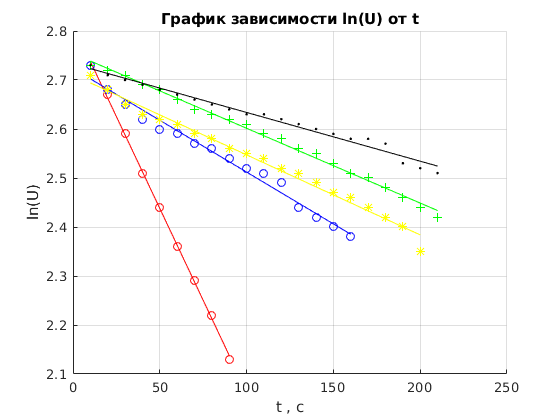

%{
x=[22.0 24.0 27.0 30.0 31.0 35.0 40.0];
y=[1.24 1.37 1.46 1.26 1.66 1.84 1.99];
% Найдем коэффициэнты полинома
a=polyfit(x,y,5),
%  Найдем значения полиномов в интервале от 20 до 40
x1=20:0.5:40;
y1=polyval(a,x1);
y0 = polyval(a,x); % расчет ф-ции в точках данных
% Погрешность аппроксимации по МНК
e=sum((y0-y).^2)/length(y)
%}



graph_1 = figure;
hold on;
    plot(OX1,  f1, 'r-');
    plot(OX1,  OY1 , 'ro');
    plot(OX2,  f2, 'b-');
    plot(OX2,  OY2 , 'bo');
    plot(OX3,  f3, 'y-');
    plot(OX3,  OY3 , 'y*');
    plot(OX4,  f4, 'g');
    plot(OX4,  OY4 , 'g+');
    plot(OX5,  f5, 'k-');
    plot(OX5,  OY5 , 'k.');
hold off;

set   (graph_1, 'Visible', 'on'); 
ylabel('ln(U)');
xlabel('t , c');
title ('График зависимости ln(U) от t');
%legend("Нужная зависимость", 'Location','northwest');
grid on; 

graph_2 = figure;
hold on;
    plot(OX6,  f6, 'r-');
    plot(OX6,  OY6 , 'ro');
hold off;
set   (graph_2, 'Visible', 'on'); 
ylabel('D, см^2/c}');
xlabel('1/P , 1/торр');
title ('График зависимости D от 1/P');
%legend("Нужная зависимость", 'Location','northwest');
grid on; 

saveas(graph_1, 'graph_1.png');

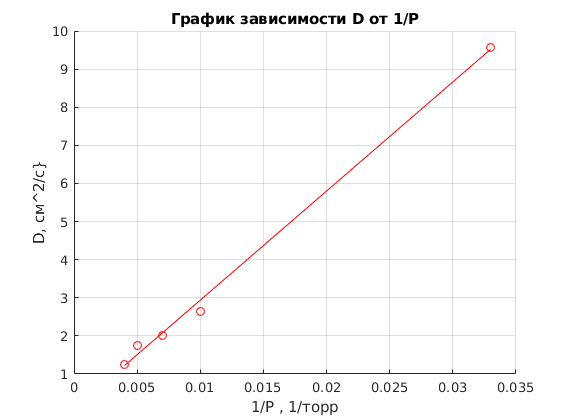

saveas(graph_2, 'graph_2.png');

#### 6. Построение графика спектров всех звёзд

%graphStars = figure;

%hold on;
%for indxGraph = 1 : numStars
%    if speed(indxGraph) > 0
%        plot(lambda, spectra(:, indxGraph), ...
%             '-', ...
%             'Linewidth', 3);
%    else 
%        plot(lambda, spectra(:, indxGraph), ...
%             '--', ...
%             'Linewidth', 1); 
%    end
%end
%hold off;

#### 7. Добавление на график названия, подписи осей, сетки и легенды

%set   (graphStars, 'Visible', 'on'); 
%xlabel('Длина волны, нм');
%ylabel(['Интенсивность, эрг/см^2/с/', char(197)]);
%title ('Спектры звёзд');
%legend(starNames);
%grid on;
%saveas(graphStars, 'spectra.png');